# Hierarchical vector interpolation

clear ; close all ; path=pwd();
[s,e]=regexp(path,'.+(?=[\\/]{1,2}examples)');
path=path(s:e); addpath(genpath(path)); clear s e path

## 1) Definition of the interpolation tree

From the leaves to the root.

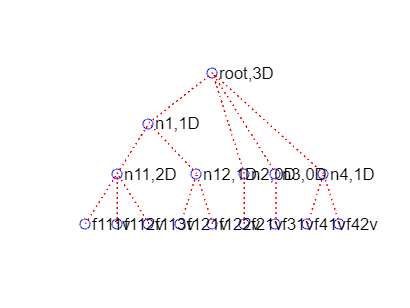

dimInput = 2;
dimOutput = 2;

defNode11.Domain = Domain(3);
f111v = VertexFunction(@(b) b.^2, @(b) [2*b(1,1,:),zeros(1,1,size(b,3));zeros(1,1,size(b,3)),2*b(2,1,:)], "f111v", dimInput, dimOutput);
f112v = VertexFunction(@(b) b.^3, @(b)  [3*b(1,1,:).^2,zeros(1,1,size(b,3));zeros(1,1,size(b,3)),3*b(2,1,:).^2], "f112v", dimInput, dimOutput);
f113v = VertexFunction(@(b) 0.1*b, @(b) ones(size(b)).*eye(2)*0.1, "f113v", dimInput, dimOutput);
defNode11.Children = [f111v,f112v,f113v];
defNode11.Label = "n11"; % Neveu convention (any unique labeling is possible)
defNode11.Penalization = Penalization("simp",2);
Node11 = Interpolation(defNode11);

defNode12.Domain = Domain(2);

f121v = VertexFunction(@(b) ones(size(b)), @(b) zeros(2,2,size(b,3)), "f121v", dimInput, dimOutput); % constant
f122v = VertexFunction(@(b) mult([1,2;3,4],b), @(b) [1,2;3,4].*ones(1,1,size(b,3)), "f122v", dimInput, dimOutput);
defNode12.Children = [f121v,f122v];
defNode12.Label = "n12";
defNode12.Penalization = Penalization("simp",2);
Node12 = Interpolation(defNode12);

defNode1.Domain = Domain(2);
defNode1.Children = [Node11,Node12];
defNode1.Label = "n1";
defNode1.Penalization = Penalization("simp",2);
Node1 = Interpolation(defNode1);


% singleton domains to keep homogeneous children of Node 0
defNode2.Domain = Domain(1);
defNode2.Children = VertexFunction(@(b) 2*b.^3, @(b)  2*[3*b(1,1,:).^2,zeros(1,1,size(b,3));zeros(1,1,size(b,3)),3*b(2,1,:).^2], "f21v", dimInput, dimOutput);
defNode2.Label = "n2";
Node2 = Interpolation(defNode2);

defNode3.Domain = Domain(1);
defNode3.Children =  VertexFunction(@(b) mult([1,2;8,4],b), @(b) [1,2;8,4].*ones(1,1,size(b,3)), "f31v", dimInput, dimOutput);
defNode3.Label = "n3";
Node3 = Interpolation(defNode3);


defNode4.Domain = Domain(2);
f41v = VertexFunction(@(b) b.^2, @(b) [2*b(1,1,:),zeros(1,1,size(b,3));zeros(1,1,size(b,3)),2*b(2,1,:)], "f41v", dimInput, dimOutput);
f42v = VertexFunction(@(b) b.^3, @(b)  [3*b(1,1,:).^2,zeros(1,1,size(b,3));zeros(1,1,size(b,3)),3*b(2,1,:).^2], "f42v", dimInput, dimOutput);
defNode4.Children = [f41v,f42v];
defNode4.Label = "n4";
defNode4.Penalization = Penalization("simp",2);
Node4 = Interpolation(defNode4);

% Finally, we define the root and the all tree

defNode0.Domain = Domain("tetra");
defNode0.Children = [Node1,Node2,Node3,Node4];
defNode0.Label = "root";
defNode0.Penalization = Penalization("simp",2);
interpHierarchicalVector = Interpolation(defNode0);

interpHierarchicalVector.plotTree();

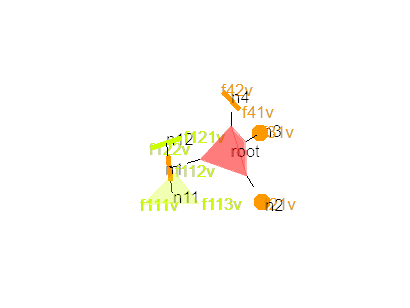

figure()
interpHierarchicalVector.plot();

## 2) Definition of the variables

### a) Coordinates in the polygon

n = 1e3; % number of evaluation points
x = interpHierarchicalVector.initializeVariable(n,"rand",1)

x = struct with fields:
    root: [1000×3 double]
      n1: [1000×1 double]
     n11: [1000×2 double]
     n12: [1000×1 double]
      n2: [1000×0 double]
      n3: [1000×0 double]
      n4: [1000×1 double]


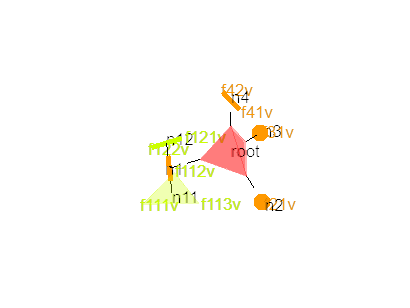

x = interpHierarchicalVector.projection(x);
figure()
interpHierarchicalVector.plot(x);

### b) Vector field

Each point $x$ is associated to a vector field value $b$.

b = rand(2,1,n);

## 3) Evaluation of the interpolation

### a) Interpolated value

tic
val = interpHierarchicalVector.eval(x,b); % value
tv1 = toc;
disp(strcat("Compute interpolated values in ",num2str(tv1*1000)," ms"))

Compute interpolated values in 7.8554 ms


### b) Derivative w. r. t. the scalar field

tic
dfda =  interpHierarchicalVector.evalda(x,b); % derivative w.r.t a
tda1 = toc;
disp(strcat("Compute interpolated a-derivative in ",num2str(tda1*1000)," ms"))

Compute interpolated a-derivative in 16.8526 ms


#### Check the Taylor expansion

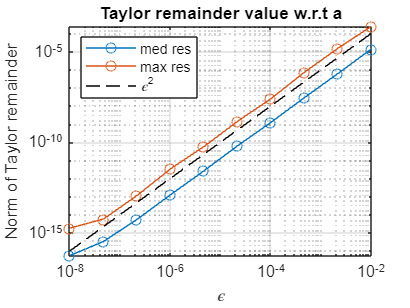

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);

for i=1:10
    pert = epsilon(i)*rand(size(b));
    valPerturbeda = interpHierarchicalVector.eval(x,b+pert);
    res(i,1,:) = vecnorm(valPerturbeda - (val + mult(dfda,pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t a")
grid on

### c) Derivative w. r. t. the position in the interpolation domain

tic
x0=x;
dfdx =  interpHierarchicalVector.evaldx(x,b); % derivative w.r.t x
tdx1 = toc;
disp(strcat("Compute interpolated x-derivative in ",num2str(tdx1*1000)," ms"))

Compute interpolated x-derivative in 26.8036 ms


#### Check the Taylor expansion

The computation of derivative in 3D domain is ill-conditionned near the boundaries. Therefore, the `epsProj `parameter sets the minimum distance between the projected points and the boundary. When `epsProj=0 `the projection is exact but the computation of derivative is wrong, and if `epsProj `is big the computation of derivative is precise but the projection is wrong. `epsProj=1e-5 `is a good tradeoff.

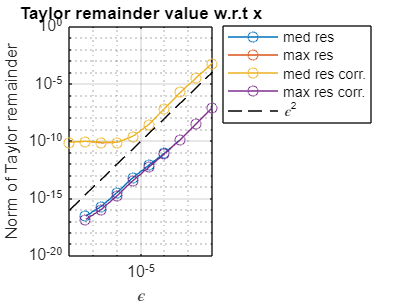

epsProj = 1e-5;
defNode0.Domain = Domain("tetra", 1, epsProj);
interpHierarchicalVector = Interpolation(defNode0);

x = interpHierarchicalVector.projection(x0);
fCorrected = interpHierarchicalVector.eval(x, b);
dfdxCorrected = interpHierarchicalVector.evaldx(x, b);

epsilon = logspace(-8,-2,10); % test for different epsilon
allLabel = [interpHierarchicalVector.getAllNodes.Label];
res = zeros(10,length(allLabel),n);
resXCorrected = zeros(10,length(allLabel),n);

for i=1:10
    for j=1:length(allLabel)
        l=allLabel(j);
        pert = epsilon(i)*rand(size(x.(l)));
        xPert = x;
        xPert.(l) = x.(l) + pert;
        xPert = interpHierarchicalVector.projection(xPert);
        pert = xPert.(l) - x.(l);
        valPerturbedx = interpHierarchicalVector.eval(xPert,b);
        pert = permute(pert,[2,3,1]);
        res(i,j,:) = vecnorm(valPerturbedx - (val + mult(dfdx.(l),pert)),2,1);
        resXCorrected(i,j,:) = vecnorm(valPerturbedx - (fCorrected + mult(dfdxCorrected.(l),pert)),2,1);
    end
end
MaxRes = max(res,[],[2,3]); medRes = median(res,[2,3]);
maxResXCorrected = max(resXCorrected,[],[2,3]); medResXCorrected = median(resXCorrected,[2,3]);

loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o'); hold on;
loglog(epsilon,maxResXCorrected,'-o',epsilon,medResXCorrected,'-o',epsilon,epsilon.^2,'k--'); hold off

legend("med res","max res", "med res corr.", "max res corr.", "\epsilon^2","Location","bestoutside")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t x")
grid on

## 4) Speed tip

To compute several times the interpolation for different $a$ without changing the position $x$ in the domain, one should first compute the shape functions once for all.

b2 = rand(2,100,n);
% slow
tic
for i=1:100
    interpHierarchicalVector.eval(x,b2(:,i,:)); % value
    interpHierarchicalVector.evalda(x,b2(:,i,:)); % derivative w.r.t a
    interpHierarchicalVector.evaldx(x,b2(:,i,:)); % derivative w.r.t x
end
tslow = toc;
disp(strcat("Computation time : ",num2str(tslow)," s"))

Computation time : 2.8881 s



% fast
tic
 % pre-computation of the shape functions
[w,dwdx] = interpHierarchicalVector.evalBasisFunction(x);
for i=1:100
    interpHierarchicalVector.eval(x,b2(:,i,:),w); % value
    interpHierarchicalVector.evalda(x,b2(:,i,:),w); % derivative w.r.t a
    interpHierarchicalVector.evaldx(x,b2(:,i,:),w,dwdx); % derivative w.r.t x
end
tfast = toc;
disp(strcat("Computation time : ",num2str(tfast)," s"))

Computation time : 1.2176 s
